# ARI - Homework 4		

% initialize
clear all
close all
clc

% useful commands
help tf 

 tf  Construct transfer function or convert to transfer function.
 
   Construction:
     SYS = tf(NUM,DEN) creates a continuous-time transfer function SYS with
     numerator NUM and denominator DEN. SYS is an object of type tf when
     NUM,DEN are numeric arrays, of type GENSS when NUM,DEN depend on tunable
     parameters (see REALP and GENMAT), and of type USS when NUM,DEN are
     uncertain (requires Robust Control Toolbox).
 
     SYS = tf(NUM,DEN,TS) creates a discrete-time transfer function with
     sample time TS (set TS=-1 if the sample time is undetermined).
 
     S = tf('s') specifies the transfer function H(s) = s (Laplace variable).
     Z = tf('z',TS) specifies H(z) = z with sample time TS.
     You can then specify transfer functions directly as expressions in S
     or Z, for example,
        s = tf('s');  H = exp(-s)*(s+1)/(s^2+3*s+1)
 
     SYS = tf

help step

 step  Step response of dynamic systems.
 
    [Y,T] = step(SYS) computes the step response Y of the dynamic system SYS. 
    The time vector T is expressed in the time units of SYS and the time 
    step and final time are chosen automatically. For multi-input systems,
    independent step commands are applied to each input channel. If SYS has 
    NY outputs and NU inputs, Y is an array of size [LENGTH(T) NY NU] where 
    Y(:,:,j) contains the step response of the j-th input channel.
 
    For state-space models, 
       [Y,T,X] = step(SYS) 
    also returns the state trajectory X, an array of size [LENGTH(T) NX NU] 
    for a system with NX states and NU inputs.
 
    For identified models (see IDMODEL),
       [Y,T,X,YSD] = step(SYS) 
    also computes the standard deviation YSD of the response Y (YSD is empty 
    if SYS does not contain parameter covariance information).
 
    [Y,...] = step(SYS

help rltool

 rltool  Opens the SISO Design Tool and sets it up for root locus design.
 
    rltool opens the SISO Design Tool with Root Locus view on.  Using this
    GUI, you can interactively design a single-input/single-output (SISO) 
    compensator using the Root Locus technique.  To import the plant model 
    into the SISO Design Tool, select the Import Model item from the File 
    menu.  By default, the feedback configuration is
 
              u --->O--->[ COMP ]--->[ PLANT ]----+---> y
                  - |                             |
                    +-----------------------------+
 
    rltool(PLANT) further specifies the plant model PLANT to be used in
    the SISO Tool.  PLANT is any linear model created with TF, ZPK, or SS.
 
    rltool(PLANT,COMP) also specifies an initial value COMP for the 
    compensator (also a linear model created with TF, ZPK, or SS).
 
    rltool(PLANT,COMP,LocationFl

help feedback

 feedback  Feedback connection of two input/output systems. 
 
    M = feedback(M1,M2) computes a closed-loop model M for the feedback loop: 
 
           u --->O---->[ M1 ]----+---> y
                 |               |           y = M * u
                 +-----[ M2 ]<---+
 
    Negative feedback is assumed and the model M maps u to y. To apply 
    positive feedback, use the syntax M = feedback(M1,M2,+1).
 
    M = feedback(M1,M2,FEEDIN,FEEDOUT,SIGN) builds the more general feedback 
    interconnection:
 
                       +------+
           v --------->|      |--------> z
                       |  M1  |
           u --->O---->|      |----+---> y
                 |     +------+    |
                 |                 |
                 +-----[  M2  ]<---+
 
    The vector FEEDIN contains indices into the input vector of M1 and
    specifies which inputs u are involved in the feedback loop. Similarly, 
    FEED

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




% type 'help' followed by the command to learn about that specific function
% using the percent sign allows comments in MATLAB
% to compile/run your livescript hit "run" at the top of your screen

## Tasks 	

*Please answer the following in the spaces provided below, justify your conclustion:	*

#### Assignment 1 – Routh table								

Determine the intervals of the gains $K$, $K_I$ of the cascade compensator, such that the closed-loop system shown below is stable. Use Routh-Hurwitz criterion. 

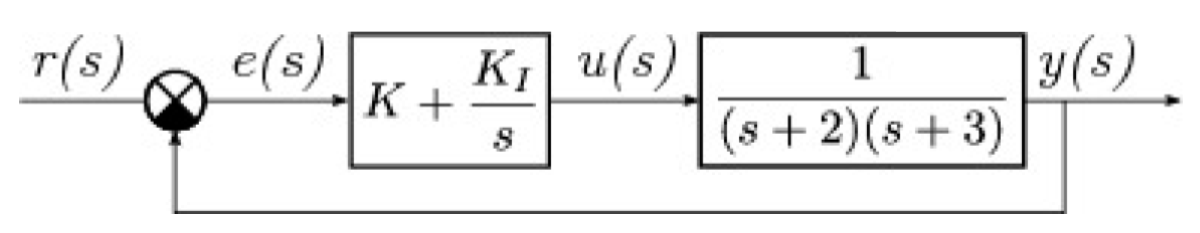

- Explain the key steps in the calculations and show important intermediate results. 					

 % insert your code here
 %syms K KI s
 %c = s*(s+2)*(s+3) + K*s + KI;
 

- Compare the original step response and the step response of the system obtained by identification. Include the plot showing how well you identified the system.

% insert your code here	


#### Assignment 2 – rltool								

Using the function hw_4_std generate a model of the second-order system with two poles and no zero. The form of the system is:


$$G\left(s\right)=\frac{1}{\left(s+a\right)\left(s+b\right)}$$
	 

Now consider the feedback system

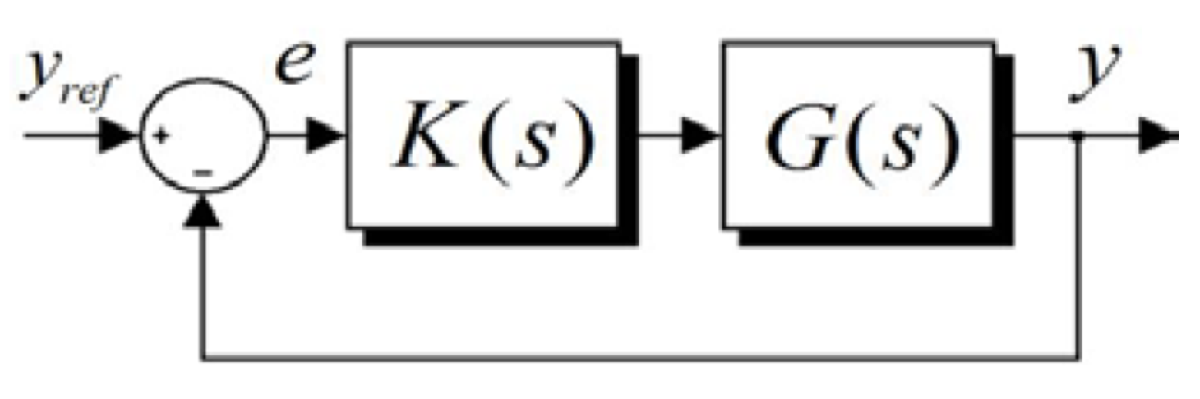

with the controller 


$$K\left(s\right)=K_p +\frac{K_I }{s}$$


- For the given system design the constants $K_p >0$, $K_I >0$ of the controller using the root-locus roles. Use rltool in Matlab. The goal is to place the poles as far away to the left (far from the imaginary axis) as possible. The damping factor must be kept at $\zeta =0\ldotp 7$. 	

% insert your code here	
syms Kp Ki
G = hw_4_std(30,05,02);
F = zpk(G)

F =
 
       1
  ------------
  (s+5) (s+48)
 
Continuous-time zero/pole/gain model.



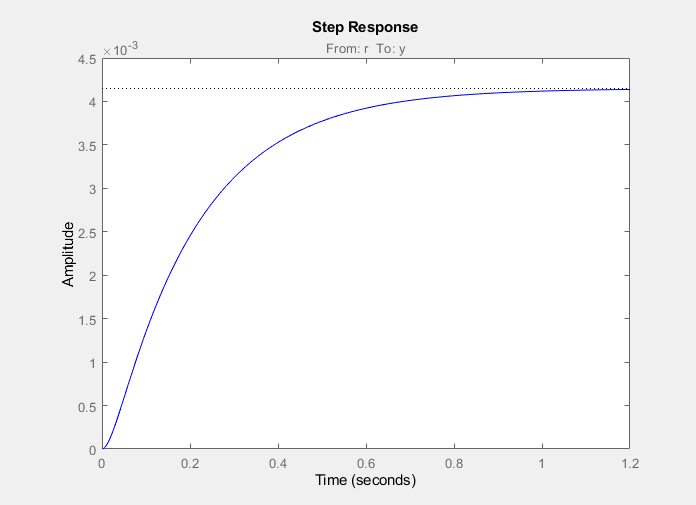

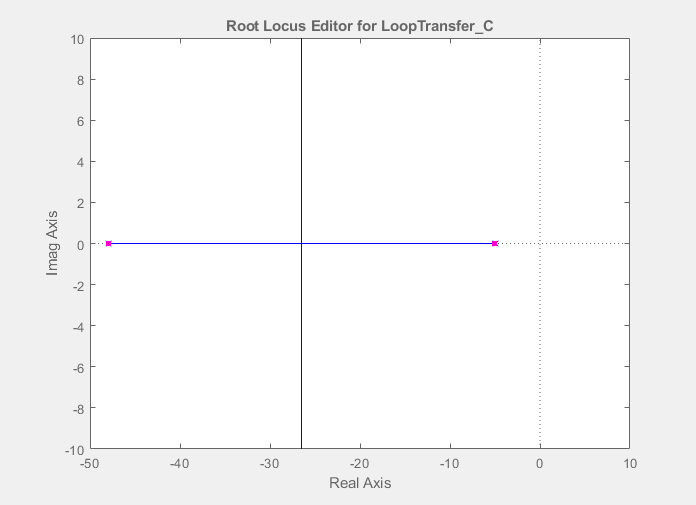

rltool(G);

- Explain your approach and show key intermediate steps. 	 

% insert your code here	

- Plot the step response of the closed-loop.

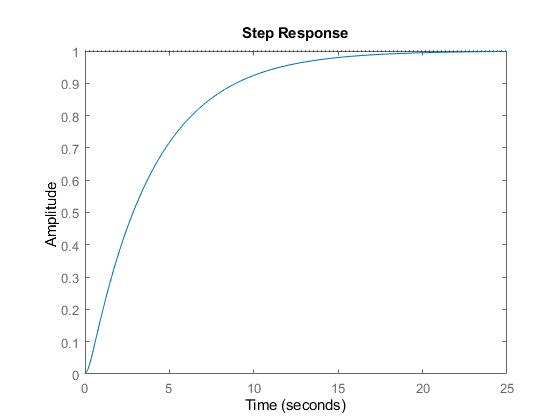

% insert your code here
step((s+60)/(s*(s+5)*(s+48) + (s+60)))

zpk((s+60)/(s*(s+5)*(s+48) + (s+60)))

- What is your steady-state regulation error?

% insert your code here
lim = 1/120;
err = 1/(1+lim)

err = 0.9917

function sys = hw_4_std(dd, mm, yy, varargin)
%	
%   hw_4_std    Data Generator for ARI2012 Homework No. 4 
%
%   The command
%       sys = hw_4_st(dd, mm, yy, varargin)
%   generates input data for ARI homework No.4 - 2012 from student's date of
%   birth
%
%	Summary: 
%		Run this function with date of birth of the student and function will return homework assignment.
%
%	Syntax: 
%       sys = hw_4_st(dd, mm, yy)
%       sys = hw_4_st(dd, mm, yy, 'display')
%
%
%	Inputs: 
%		required: 
%			date of birth (dd - day, mm - month, yy - year)
%		optional:
%			display - to display results
%
%	Outputs:
%		sys - system transfer function in zero-pole-gain format
%
%   Example:
%       >> sys = hw_4_st(25, 1, 54)
%
%       Zero/pole/gain:
%             1
%       ------------
%       (s+1) (s+24)
%
%       >> class(sys)
%       ans =
%       zpk

%			
%	Author: 
%		Kamil Dolinsky (last modified 28.2.2011)
%		MIchael Sebek  (modified 08-Feb-2012)

	[dd, mm, yy, display] = parseInput(dd, mm, yy, varargin{:});
	
	sys = zpk([],[-mm, -(6*(mm+round(dd/10)))],1);
	
	if display
		fprintf('Transfer function for assignment is \n')
		sys
	end
	
end

function [dd, mm, yy, display] = parseInput(dd, mm, yy, varargin)
	p = inputParser;
	p.addRequired('dd',@(x)isa(x,'numeric')&& size(x,1) == 1 && size(x,2) == 1 && x >= 1 && x <= 31 && mod(x,1) == 0);
	p.addRequired('mm',@(x)isa(x,'numeric')&& size(x,1) == 1 && size(x,2) == 1 && x >= 1 && x <= 12 && mod(x,1) == 0);
	p.addRequired('yy',@(x)isa(x,'numeric')&& size(x,1) == 1 && size(x,2) == 1 && x >= 0 && x <= 99 && mod(x,1) == 0);
	p.addOptional('display',nargout == 0,@(x)isa(x,'logical'));

	p.parse(dd, mm, yy, varargin{:});

	dd = p.Results.dd;
	mm = p.Results.mm;
	yy = p.Results.yy;
	display = p.Results.display;
end
